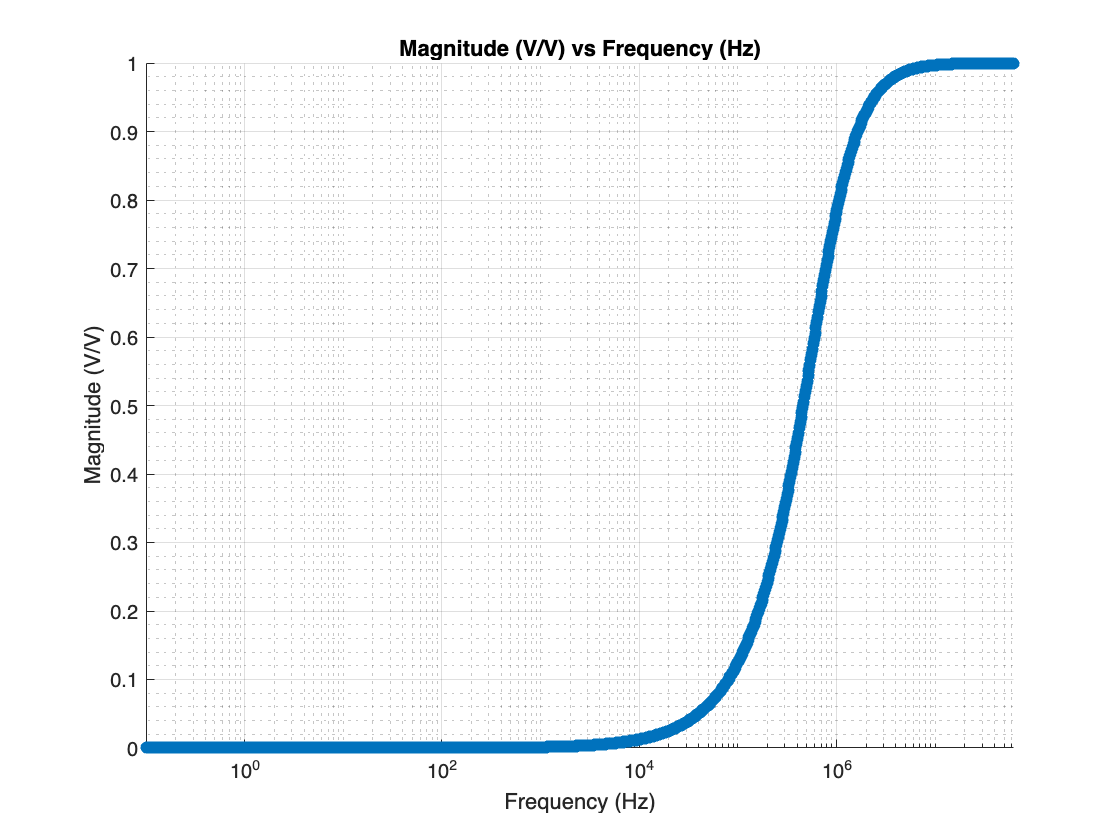

% Define the constants
R1 = 20; % ohms
C1 = 10e-9; % farads (10 nF)

% Define the specific frequencies to include
specific_frequencies = [1000, 10000, 100000, 1000000, 10000000];

% Generate the frequency vector from 0.1 Hz to 63E6 Hz, include specific frequencies
f_min = 0.1; % Hz
f_max = 63E6; % Hz
f = logspace(log10(f_min), log10(f_max), 1000);
f = sort(union(f, specific_frequencies));

% Calculate angular frequency
omega = 2 * pi * f;

% Calculate the transfer function H(jw) = jwC1R1 / (jwC1R1 + 1)
H = (1i .* omega .* C1 .* R1) ./ (1 + 1i .* omega .* C1 .* R1);

% Calculate the magnitude in V/V
mag_VV = abs(H);

% Calculate the magnitude in dB
mag_dB = 20 * log10(mag_VV);

% Plot 1: Magnitude in V/V versus frequency in Hz
figure;
scatter(f, mag_VV, 'filled');
set(gca, 'XScale', 'log'); % Set X-axis to logarithmic scale
grid on; % Major grid
grid minor; % Minor grid
title('Magnitude (V/V) vs Frequency (Hz)');
xlabel('Frequency (Hz)');
ylabel('Magnitude (V/V)');
xlim([f_min f_max]);

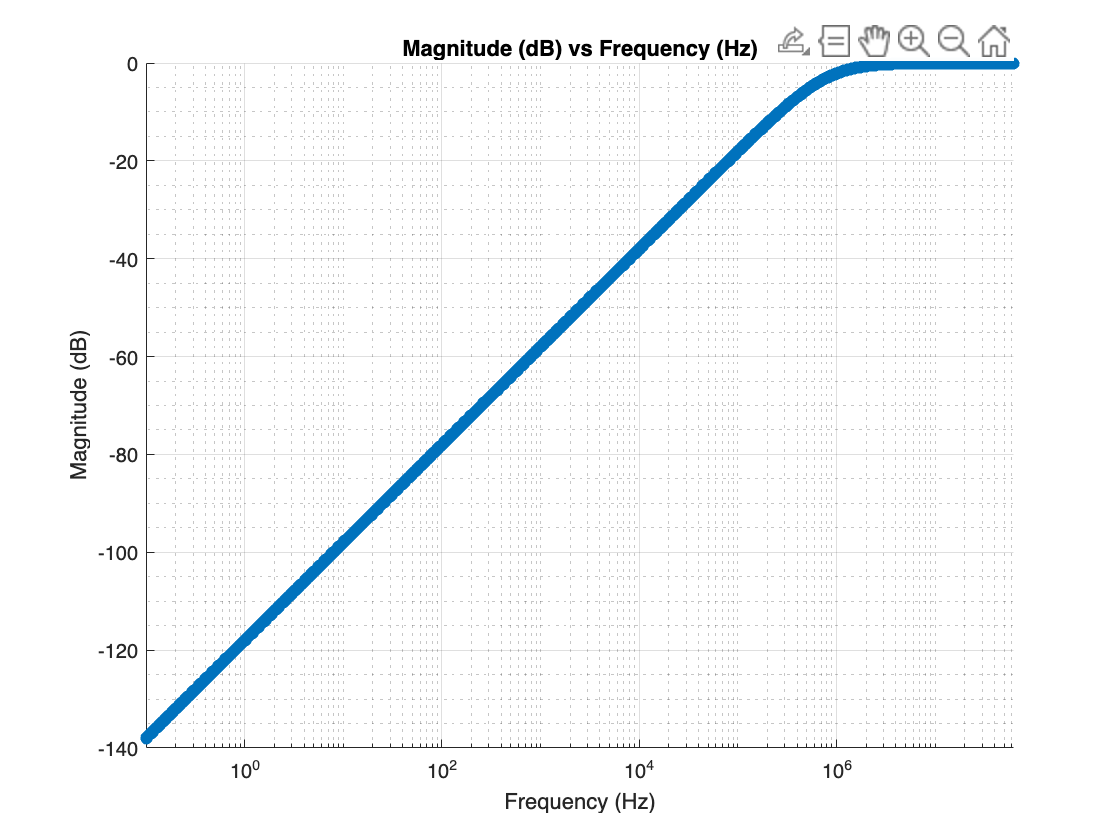


% Plot 2: Magnitude in dB versus frequency in Hz
figure;
scatter(f, mag_dB, 'filled');
set(gca, 'XScale', 'log'); % Set X-axis to logarithmic scale
grid on; % Major grid
grid minor; % Minor grid
title('Magnitude (dB) vs Frequency (Hz)');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
xlim([f_min f_max]);

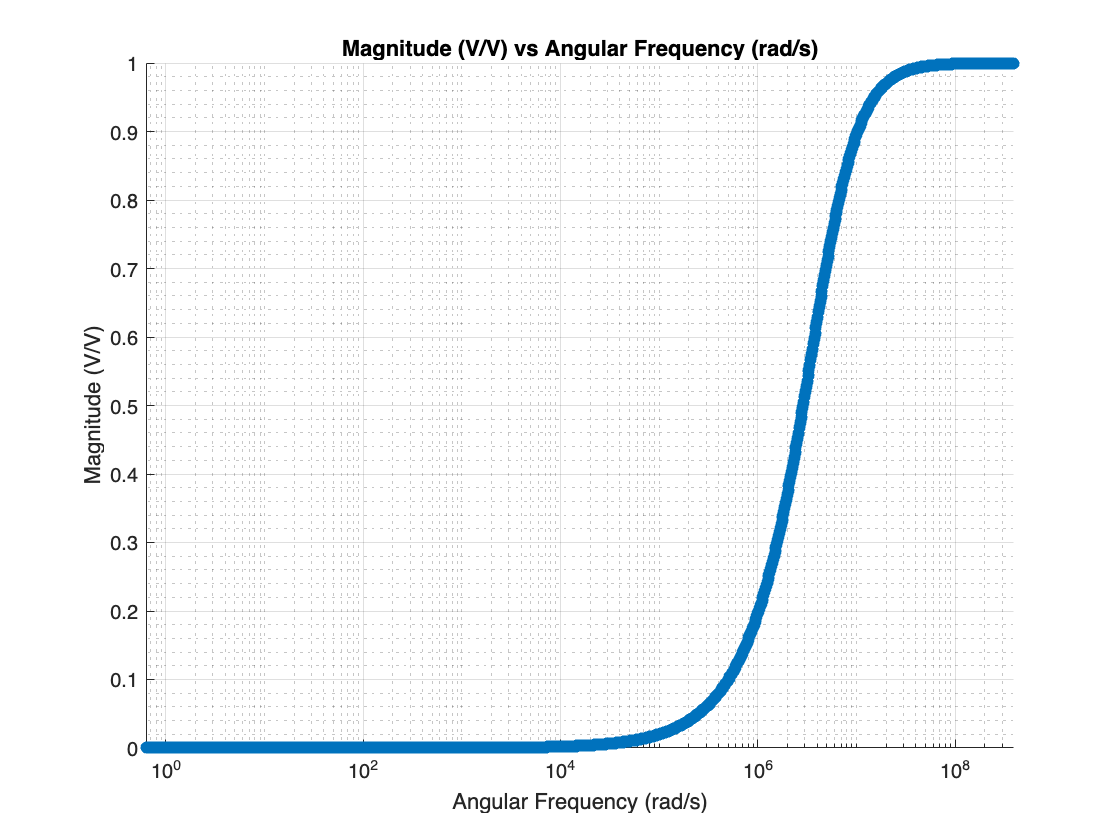

% ... (Continuation from the previous script)

% Plot 3: Magnitude in V/V versus angular frequency in rad/s
figure;
scatter(omega, mag_VV, 'filled');
set(gca, 'XScale', 'log'); % Set X-axis to logarithmic scale
grid on; % Major grid
grid minor; % Minor grid
title('Magnitude (V/V) vs Angular Frequency (rad/s)');
xlabel('Angular Frequency (rad/s)');
ylabel('Magnitude (V/V)');
xlim([2*pi*f_min 2*pi*f_max]);

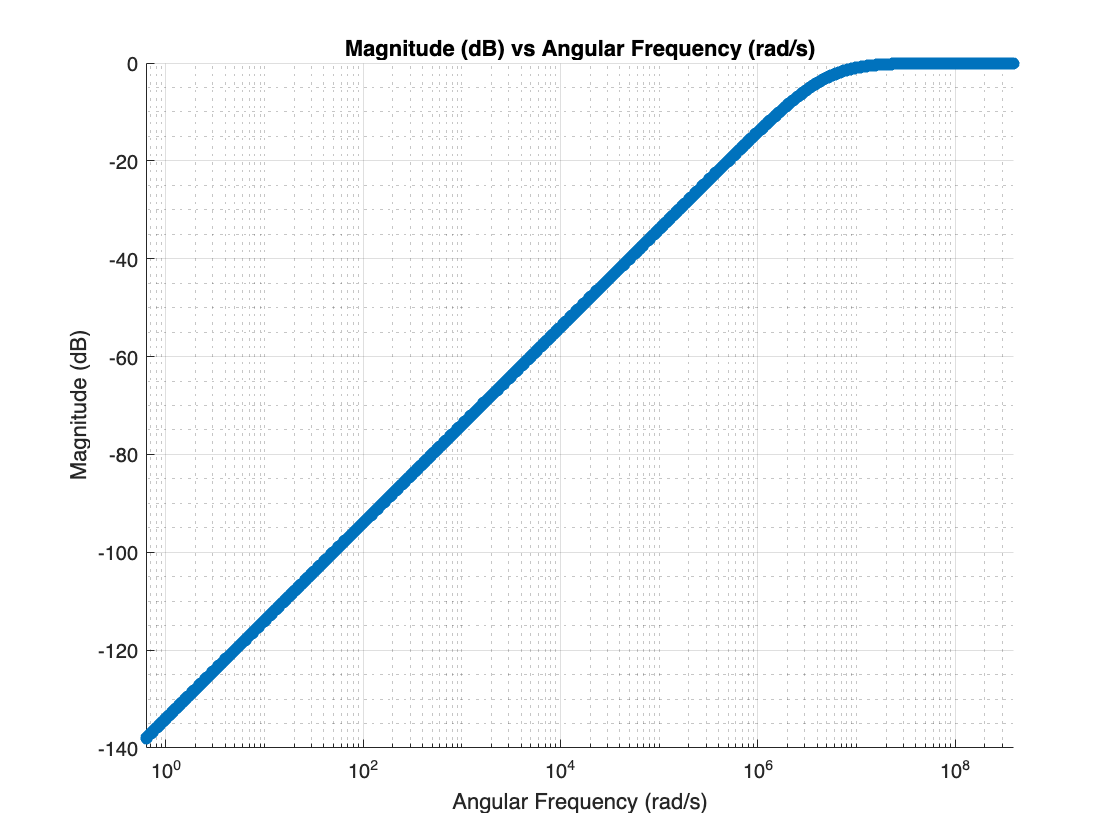


% Plot 4: Magnitude in dB versus angular frequency in rad/s
figure;
scatter(omega, mag_dB, 'filled');
set(gca, 'XScale', 'log'); % Set X-axis to logarithmic scale
grid on; % Major grid
grid minor; % Minor grid
title('Magnitude (dB) vs Angular Frequency (rad/s)');
xlabel('Angular Frequency (rad/s)');
ylabel('Magnitude (dB)');
xlim([2*pi*f_min 2*pi*f_max]);

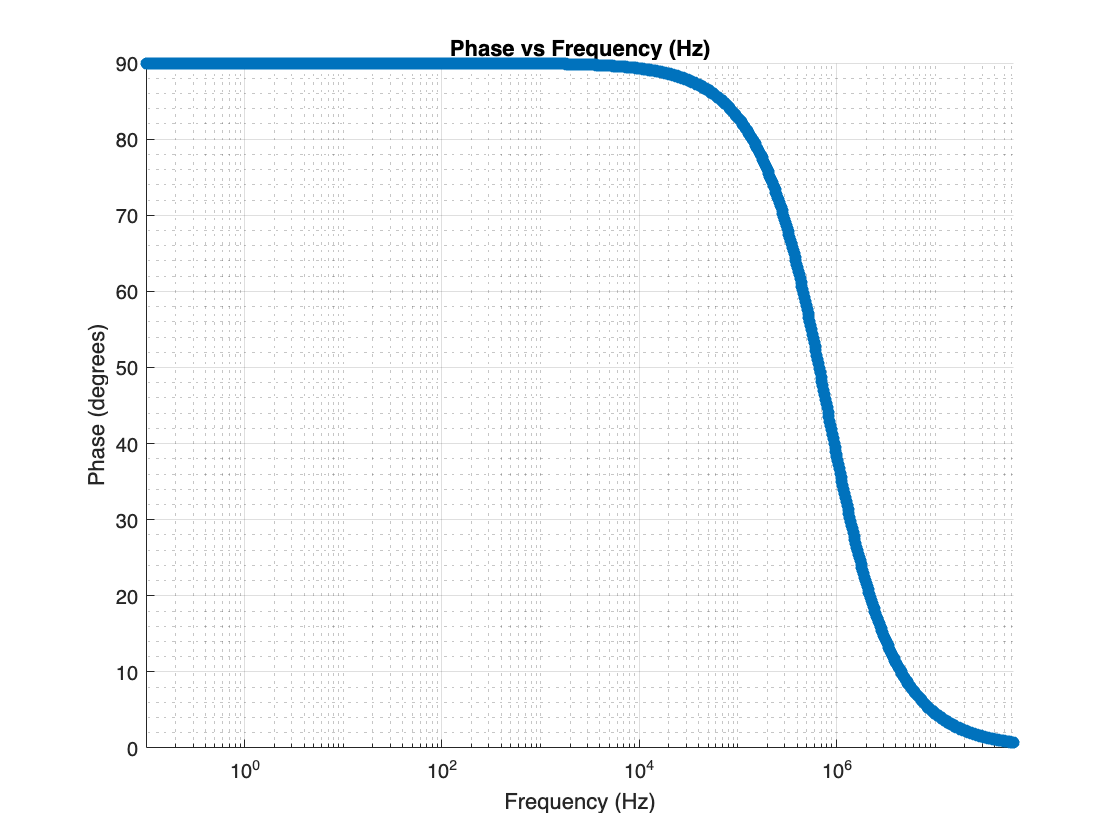


% Calculate the phase in degrees
phase_degrees = rad2deg(angle(H));

% Plot 5: Phase vs Frequency in Hz
figure;
scatter(f, phase_degrees, 'filled');
set(gca, 'XScale', 'log'); % Set X-axis to logarithmic scale
grid on; % Major grid
grid minor; % Minor grid
title('Phase vs Frequency (Hz)');
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
xlim([f_min f_max]);

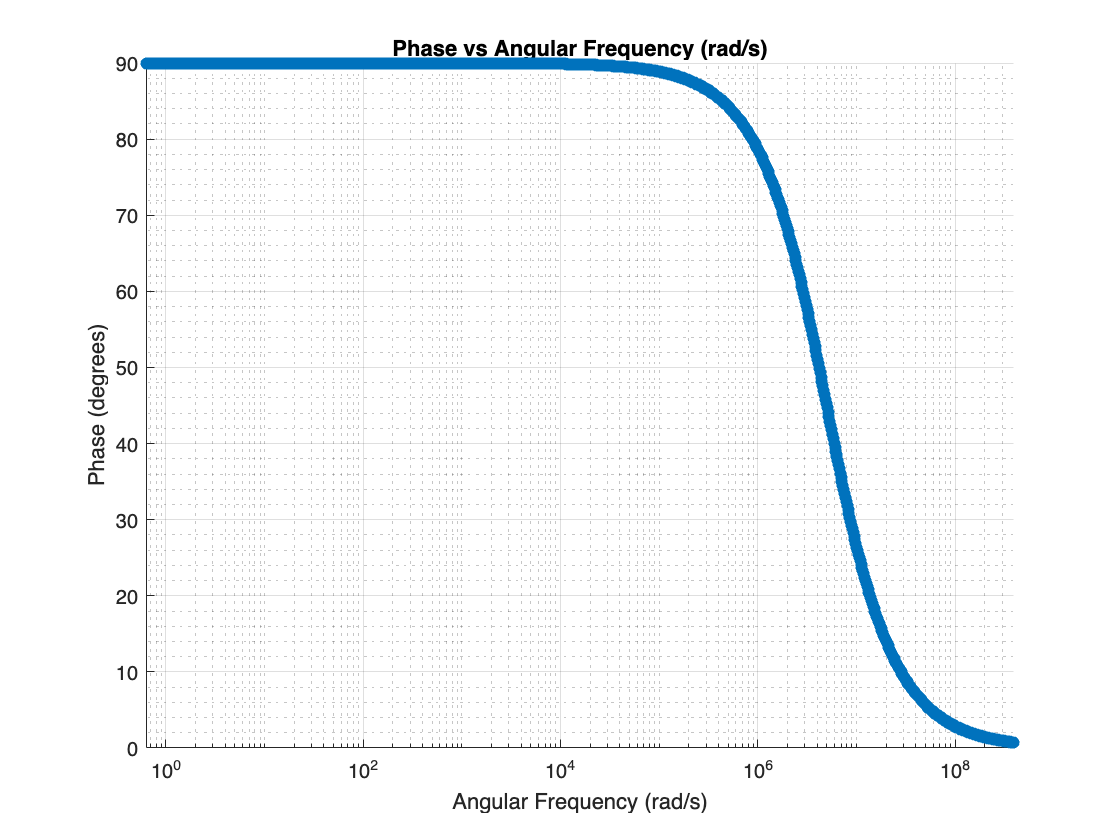


% Plot 6: Phase vs Angular Frequency in rad/s
figure;
scatter(omega, phase_degrees, 'filled');
set(gca, 'XScale', 'log'); % Set X-axis to logarithmic scale
grid on; % Major grid
grid minor; % Minor grid
title('Phase vs Angular Frequency (rad/s)');
xlabel('Angular Frequency (rad/s)');
ylabel('Phase (degrees)');
xlim([2*pi*f_min 2*pi*f_max]);